clc
clear
close all
addpath('Trayectorias\')

Posición inicial

posX = 0.15;
posY = 0.2;
posZ = 0.75;
Ex = -45;
Ey = 0;
Ez = 0;

punto1.pos = [posX,posY,posZ];
punto1.rot = [Ex,Ey,Ez];

Posición Final

posX = 0.15;
posY = 0.1;
posZ = 0.75;
Ex = -45;
Ey = 0;
Ez = 0;

punto2.pos = [posX,posY,posZ];
punto2.rot = [Ex,Ey,Ez];

Precisión(desviación respecto a recta entre puntos)

precision = 0.05

precision = 0.0500

Calculo


% Vectores de trayectoria de articulaciones
[H_A01,H_A02,H_A03,H_A04,H_A05,H_A06] = initTrajectory();
if false
    forcePopupFigure()
end
[theta1,theta2,theta3,theta4,theta5,theta6]=inverse(punto1.pos,punto1.rot,-1,1,-1,true);

Angles:        -θ1: 44.83       -θ2: -103.24       -θ3: 178.14       -θ4: 137.79       -θ5: 48.28       -θ6: 156.55

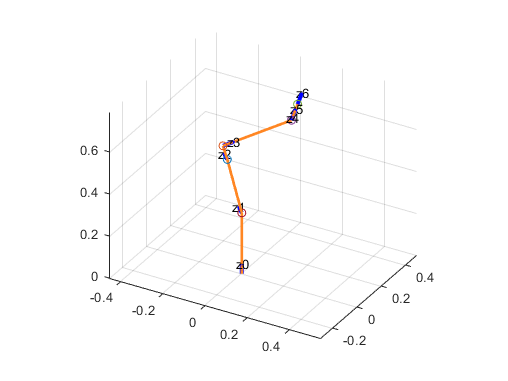

punto1.angles= [theta1,theta2,theta3,theta4,theta5,theta6];
[A01,A02,A03,A04,A05,A06] = plotRobot([theta1,theta2,theta3,theta4,theta5,theta6],false);
[H_A01,H_A02,H_A03,H_A04,H_A05,H_A06] = saveTrajectory(A01,A02,A03,A04,A05,A06,H_A01,H_A02,H_A03,H_A04,H_A05,H_A06);



%Punto en mitad de los puntos
m1.pos = (punto2.pos-punto1.pos)/2+punto1.pos;
m1.rot = (punto1.rot)

m1 = struct with fields:
    pos: [0.1500 0.1500 0.7500]
    rot: [-45 0 0]


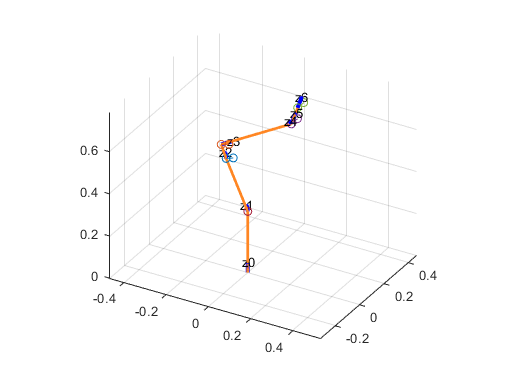

[theta1,theta2,theta3,theta4,theta5,theta6]=inverse(m1.pos,m1.rot,-1,1,-1,false);
[A01,A02,A03,A04,A05,A06] = plotRobot([theta1,theta2,theta3,theta4,theta5,theta6],false);
[H_A01,H_A02,H_A03,H_A04,H_A05,H_A06] = saveTrajectory(A01,A02,A03,A04,A05,A06,H_A01,H_A02,H_A03,H_A04,H_A05,H_A06);


%punto en mitad de movimiento de articualaciones
%punto final
[theta1,theta2,theta3,theta4,theta5,theta6]=inverse(punto2.pos,punto2.rot,-1,1,-1,false);
punto2.angles= [theta1,theta2,theta3,theta4,theta5,theta6];

for i = 1:6

  m1star.angles(i) =  rad2deg(angdiff(deg2rad(punto1.angles(i)),deg2rad(punto2.angles(i))))/2+punto1.angles(i);
end

% punto1.angles
% m1star.angles
% punto2.angles
m1star.pos = A06(1:3,4)'

m1star = struct with fields:
    angles: [31.4732 -108.2916 181.6012 134.8299 56.3871 168.6861]
       pos: [0.1500 0.1500 0.7500]



%punto final
[theta1,theta2,theta3,theta4,theta5,theta6]=inverse(punto2.pos,punto2.rot,-1,1,-1,false);
punto2.angles= [theta1,theta2,theta3,theta4,theta5,theta6];
[A01,A02,A03,A04,A05,A06] = plotRobot([theta1,theta2,theta3,theta4,theta5,theta6],true);

Final Position:    AXIS:       -x: (1, 1.8562e-16, 5.5511e-17) 
       -y: (-1.3357e-16, 0.70711, 0.70711) 
       -z: (2.4286e-16, -0.70711, 0.70711) 
   POS:       -x: (0.15) 
       -y: (0.1) 
       -z: (0.75) 
Angles:        -θ1: 18.12       -θ2: -113.34       -θ3: -174.94       -θ4: 131.87       -θ5: 64.49       -θ6: -179.18

brazo = 0.1578

Brazo izq: -1Codo arriba 1No flip 1

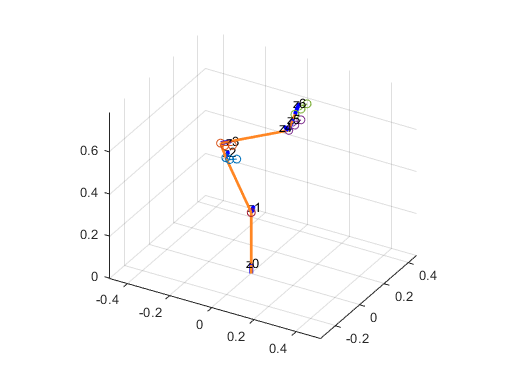

[H_A01,H_A02,H_A03,H_A04,H_A05,H_A06] = saveTrajectory(A01,A02,A03,A04,A05,A06,H_A01,H_A02,H_A03,H_A04,H_A05,H_A06);

hold on

[A01,A02,A03,A04,A05,A06] = plotRobot(m1star.angles,true);

Final Position:    AXIS:       -x: (1, 0.0018549, 6.9979e-05) 
       -y: (-0.0013865, 0.72138, 0.69254) 
       -z: (0.0012341, -0.69254, 0.72138) 
   POS:       -x: (0.1573) 
       -y: (0.14616) 
       -z: (0.75208) 
Angles:        -θ1: 31.47       -θ2: -108.29       -θ3: 181.60       -θ4: 134.83       -θ5: 56.39       -θ6: 168.69

brazo = 0.1844

Brazo izq: -1Codo arriba 1No flip 1

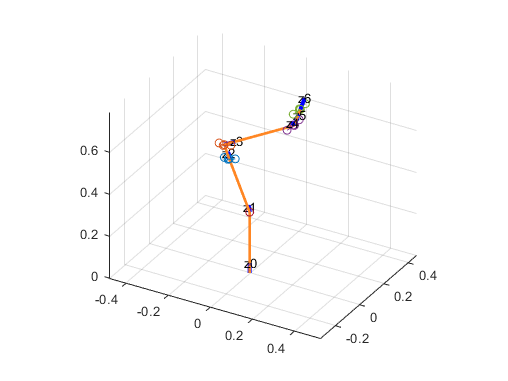

[H_A01,H_A02,H_A03,H_A04,H_A05,H_A06] = saveTrajectory(A01,A02,A03,A04,A05,A06,H_A01,H_A02,H_A03,H_A04,H_A05,H_A06);



error = point_to_line_distance(m1star.pos,punto1.pos,punto2.pos)

error = 2.7756e-17

if (error > precision)
    fprintf("hace falta un punto intermedio")

else
    fprintf("No hace falta un punto intermedio")
end

No hace falta un punto intermedio




figure()

% while (error)




